## Importation du fichier CSV

% Lecture du fichier CSV
data = readtable("speed_log0.csv");

% Extraction des colonnes
time_ms = data.time_ms;
V1 = data.V1_rpm;
V2 = data.V2_rpm;
V3 = data.V3_rpm;
V4 = data.V4_rpm;

% Conversion du temps en secondes
time_s = time_ms / 1000;

## Graphique de la vitesse de la roue V1

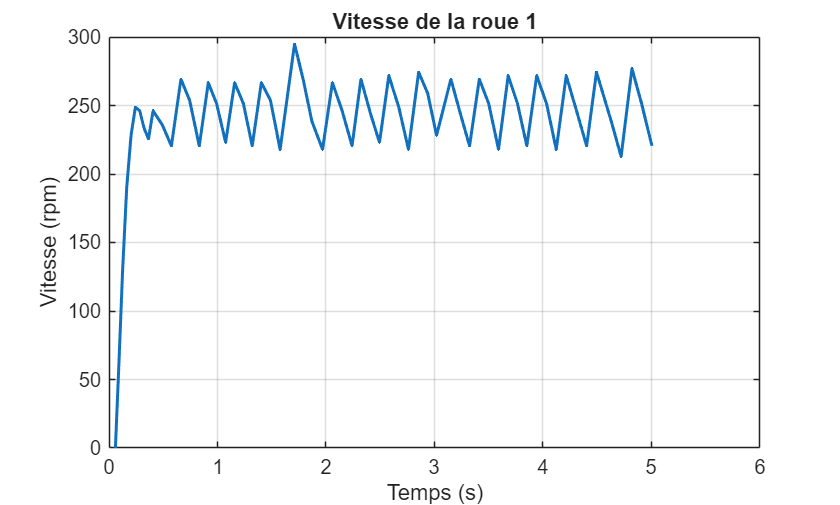

figure
plot(time_s, V1, 'LineWidth', 1.5)
grid on
xlabel('Temps (s)')
ylabel('Vitesse (rpm)')
title('Vitesse de la roue 1')

## Graphique de la vitesse des 4 roues

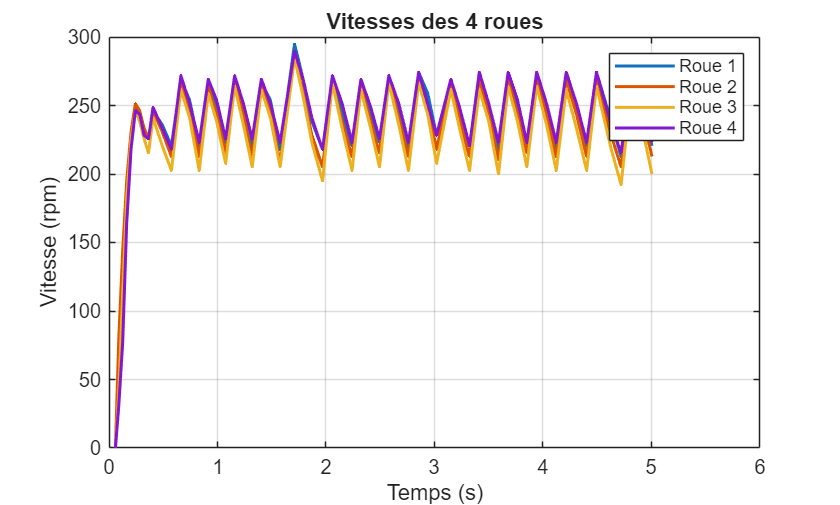

figure
plot(time_s, V1, 'LineWidth', 1.5)
hold on
plot(time_s, V2, 'LineWidth', 1.5)
plot(time_s, V3, 'LineWidth', 1.5)
plot(time_s, V4, 'LineWidth', 1.5)
grid on
xlabel('Temps (s)')
ylabel('Vitesse (rpm)')
title('Vitesses des 4 roues')
legend('Roue 1', 'Roue 2', 'Roue 3', 'Roue 4')

## Graphique de la vitesse de la roue V1 par rapport à la consigne

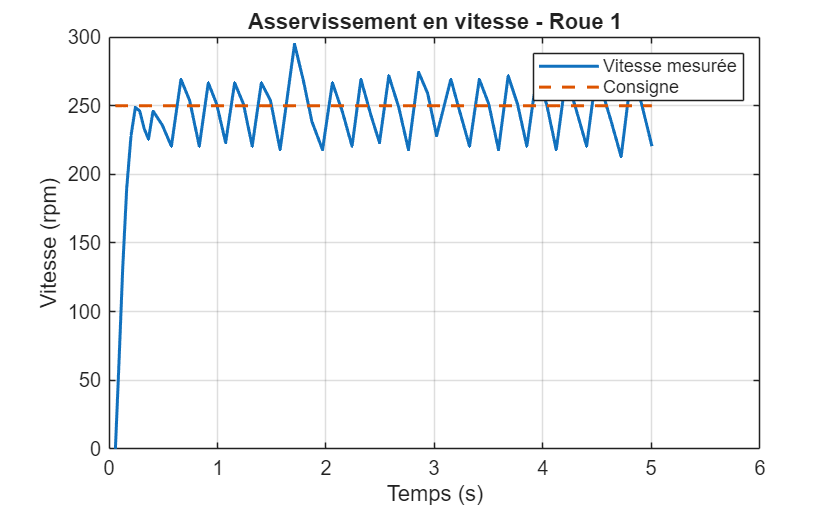

consigne = 250 * ones(size(time_s));

figure
plot(time_s, V1, 'LineWidth', 1.5)
hold on
plot(time_s, consigne, '--', 'LineWidth', 1.5)
grid on
xlabel('Temps (s)')
ylabel('Vitesse (rpm)')
title('Asservissement en vitesse - Roue 1')
legend('Vitesse mesurée', 'Consigne')

## Graphique de l'erreur de la vitesse de la roue V1

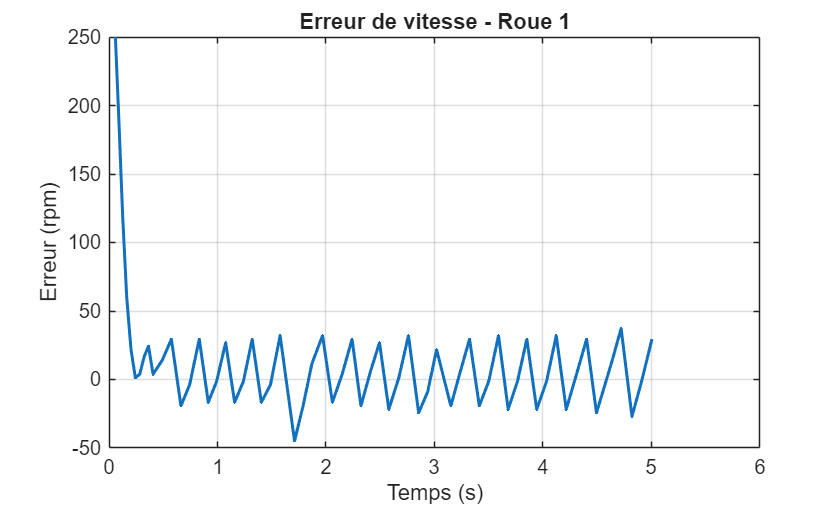

erreur = consigne - V1;

figure
plot(time_s, erreur, 'LineWidth', 1.5)
grid on
xlabel('Temps (s)')
ylabel('Erreur (rpm)')
title('Erreur de vitesse - Roue 1')